## Settings for simulink model initialization and data analysis

close all
clear all
clc
beep off
pm_addunit('percent', 0.01, '1');
options = bodeoptions;
options.FreqUnits = 'Hz';
simlength = 3.75;
% simlength = 2;
transmission_delay = 125e-6*2;


### Settings voltage application

application400 = 0;
application690 = 1;
application480 = 0;

### Settings for speed control or wind application

use_torque_curve = 1;
use_speed_control = 0;

### Settings for CCcaller versus Simulink

use_observer_from_simulink_module_1 = 0;
use_observer_from_ccaller_module_1 = 1 - use_observer_from_simulink_module_1;

use_current_controller_from_simulink_module_1 = 0;
use_current_controller_from_ccaller_module_1 = 1 - use_current_controller_from_simulink_module_1;

use_moving_average_from_ccaller = 1;
mavarage_filter_frequency_base_order = 2; % 2 means 100Hz, 1 means 50Hz

## Grid Emulator Settings

grid_emulator;

## STEPUP Settings and initialization

fPWM_STEPUP = 8e3;
tPWM_STEPUP = 1/fPWM_STEPUP;
dead_time_STEPUP = 0;
ts_stepup = 1/fPWM_STEPUP;
z_stepup =tf('z',ts_stepup);

Pnom = 275e3;
ubattery = 400;
% ubattery = 960;
idc_bez = Pnom/ubattery;
kp_ib = 0.5;
ki_ib = 18;

Lb = 250e-6;
RLb = 25e-3;
Cdc = 7.2e-3;
rho = 0.1;
A = [0, rho/Cdc; -rho/Lb 0];
lambda = eig(A);

## AFE Settings and Initialization

### Nominal DClink voltage seting

if (application690 == 1)
    Vdc_bez = 1070; % DClink voltage reference
elseif (application480 == 1)
    Vdc_bez = 750; % DClink voltage reference
else
    Vdc_bez = 660; % DClink voltage reference
end

### Switching frequencies, sampling time and deadtime

fPWM_AFE = 4e3;
tPWM_AFE = 1/fPWM_AFE;


dead_time_AFE = 0;
delay_pwm = 0;
delayAFE_modB=2*pi*fPWM_AFE*delay_pwm; 
delayAFE_modA=0;
delayAFE_modC=0;

ts_afe = 1/fPWM_AFE/2; % Sampling time of the control AFE as well as INVERTER
tc = ts_afe/100;

s=tf('s');
z_afe=tf('z',ts_afe);

t_misura = simlength - 0.025;
Nc = ceil(t_misura/tc);
Ns_afe = ceil(t_misura/ts_afe);
Ns_stepup = ceil(t_misura/ts_stepup);

### FRT Settings

enable_frt_1 = 0;
enable_frt_2 = 1 - enable_frt_1;

% deep data for frt type 2
deepPOSxi = 0.5

deepPOSxi =    0.500000000000000

deepNEGxi = 0

deepNEGxi =      0

deepNEGeta = 0.5

deepNEGeta =    0.500000000000000

#### FRT, and other fault timing settings

test_index    = 25;
test_subindex = 4;

asymmetric_error_type = 0;  
% 0 -> Variant C, two phase, 
% 1 -> Variant D, single phase

start_time_grid_switch_open = 1e3;
start_time_LVRT = 2.0e3;
time_start_motor_control = 0.035;

time_aux_power_supply_fault = 1e3;
time_phase_fault = 1e3;
start_load = 0.25;


#### FRT gain factor for grid support

settle_time = 0.15;
k_frt_ref = 2;

#### Reactive current limits for grid support


i_grid_pos_eta_lim = 1;
i_grid_neg_xi_lim = 0.5;
i_grid_neg_eta_lim = 0.5;


#### Reactive current Limits - Red. Dyn. grid support

i_grid_pos_eta_red_lim = 0.1;
i_grid_neg_eta_red_lim = 0.1;
i_grid_neg_xi_red_lim = 0.1;


#### Grid voltage derivate implemented with double integrator observer

Aso = [0 1; 0 0];
Asod = eye(2)+Aso*ts_afe;
Cso = [1 0];
omega_rso = 2*pi*50;
p2place = [-1 -4]*omega_rso;
p2placed = exp(p2place*ts_afe);
Kd = (acker(Asod',Cso',p2placed))';
l1 = Kd(2)

l1 =   44.782392633890389

l2 = Kd(1)

l2 =    0.183872841045359

### Current sensor endscale, and quantization

adc_quantization = 1/2^11;
Imax_adc = 1049.835;
CurrentQuantization = Imax_adc/2^11;

### Voltage sensor endscale, and quantization

Umax_adc = 1500;
VoltageQuantization = Umax_adc/2^11;

### DClink, and dclink-brake parameters

Vdc_ref = Vdc_bez; % DClink voltage reference
Rprecharge = 1; % Resistance of the DClink pre-charge circuit
Pload = 250e3;
Rbrake = 4;
CFi = 900e-6*8;


#### DClink Lstray model

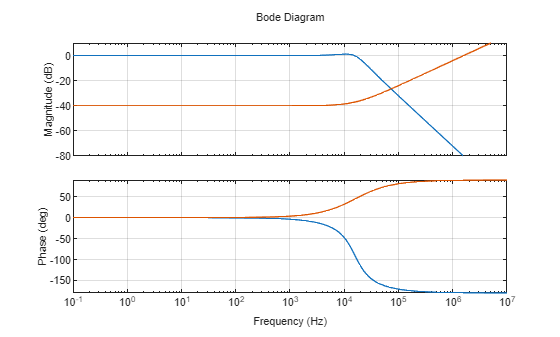

Lstray_dclink = 100e-9;
RLstray_dclink = 10e-3;
C_HF_Lstray_dclink = 15e-6;
R_HF_Lstray_dclink = 22000;
Z_HF_Lstray_dclink = 1/s/C_HF_Lstray_dclink + R_HF_Lstray_dclink;
Z_LF_Lstray_dclink = s*Lstray_dclink + RLstray_dclink;
Z_Lstray_dclink = Z_HF_Lstray_dclink*Z_LF_Lstray_dclink/(Z_HF_Lstray_dclink+Z_LF_Lstray_dclink);
ZCFi = 7/s/CFi;
sys_dclink = minreal(ZCFi/(ZCFi+Z_Lstray_dclink));
figure; bode(sys_dclink,Z_Lstray_dclink,options); grid on

### LCL switching filter

if (application690 == 1)
    LFu1_AFE = 0.5e-3;
    RLFu1_AFE = 157*0.05*LFu1_AFE;
    LFu1_AFE_0 = LFu1_AFE;
    RLFu1_AFE_0 = RLFu1_AFE/3;
    CFu = (100e-6*2);
    RCFu = (50e-3);
else
    LFu1_AFE = 0.33e-3;
    RLFu1_AFE = 157*0.05*LFu1_AFE;
    LFu1_AFE_0 = LFu1_AFE;
    RLFu1_AFE_0 = RLFu1_AFE/3;
    CFu = (185e-6*2);
    RCFu = (50e-3);
end

### DClink voltage control parameters

Vdc_nom = Vdc_bez;
Vdc_norm_ref = Vdc_ref/Vdc_nom;

kp_vs = 1.45;
ki_vs = 45;

% kp_vs = 0.85;
% ki_vs = 35;

### AFE current control parameters

#### Resonant PI

kp_afe = 0.6;
ki_afe = 45;
delta = 0.05;
res = s/(s^2 + 2*delta*omega_grid_nom*s + (omega_grid_nom)^2);

Ares = [0 1; -omega_grid_nom^2 -2*delta*omega_grid_nom];
Bres = [0; 1];
Cres = [0 1];
Aresd = eye(2) + Ares*ts_afe;
Bresd = Bres*ts_afe;
Cresd = Cres;

### Grid Normalization Factors

Vgrid_phase_normalization_factor = Vphase2*sqrt(2);
pll_i1 = 80;
pll_p = 1;
pll_p_frt = 0.2;
Vmax_ff = 1.1;
Igrid_phase_normalization_factor = 250e3/Vphase2/3/0.9*sqrt(2);
ixi_pos_ref_lim = 1.6;
ieta_pos_ref_lim = 1.0;
ieta_neg_ref_lim = 0.5;

### Double Integrator Observer for PLL

Arso = [0 1; 0 0];
Crso = [1 0];
omega_rso = 2*pi*50;
polesrso = [-1 -4]*omega_rso;
Lrso = acker(Arso',Crso',polesrso)';
Adrso = eye(2) + Arso*ts_afe;
polesdrso = exp(ts_afe*polesrso);
Ldrso = acker(Adrso',Crso',polesdrso)'

Ldrso =    0.183872841045359
  44.782392633890389


### PLL DDSRF

use_advanced_pll = 0;
use_dq_pll_ccaller = 0;
pll_i1_ddsrt = pll_i1/2;
pll_p_ddsrt = pll_p/2;
omega_f = 2*pi*50;
ddsrf_f = omega_f/(s+omega_f);
ddsrf_fd = c2d(ddsrf_f,ts_afe);

### First Harmonic Tracker for Ugrid cleaning

omega0 = 2*pi*50;
Afht = [0 1; -omega0^2 -0.05*omega0] % impianto nel continuo

Afht = 1.0e+04 *

                   0   0.000100000000000
  -9.869604401089358  -0.001570796326795


Cfht = [1 0];
poles_fht = [-1 -4]*omega0;
Lfht = acker(Afht',Cfht',poles_fht)' % guadagni osservatore nel continuo

Lfht = 1.0e+05 *

   0.015550883635269
   2.716608611399846


Ad_fht = eye(2) + Afht*ts_afe % impianto nel discreto

Ad_fht =    1.000000000000000   0.000125000000000
 -12.337005501361698   0.998036504591506


polesd_fht = exp(ts_afe*poles_fht);
Ld_fht = Lfht*ts_afe % guadagni osservatore nel discreto

Ld_fht =    0.194386045440868
  33.957607642498068


### IGBT and snubber data

Ron = 3.5e-3;
Irr = 750;
Lstray_dclink

Lstray_dclink =      1.000000000000000e-07

Csnubber = Irr^2*Lstray_dclink/Vdc_nom^2

Csnubber =      4.913092846536815e-08

Rsnubber = 1/(Csnubber*fPWM_AFE)/100

Rsnubber =   50.884444444444455

Vgamma = 1.6;
i_swlosses_base_ff650r17ie4 = 650;
u_swlosses_base_ff650r17ie4 = 900;
eon_ff650r17ie4 = 0.3;
eoff_ff650r17ie4 = 0.205;
vcesat_ff650r17ie4 = 1.75;

### Reactive current control gains

kp_rc_grid = 0.35;
ki_rc_grid = 35;

kp_rc_pos_grid = 0.35;
ki_rc_pos_grid = 35;
kp_rc_neg_grid = 0.35;
ki_rc_neg_grid = 35;

### Settings for First Order Low Pass Filters

#### LPF 50Hz in state space (for initialization)

fcut = 50;
fof = 1/(s/(2*pi*fcut)+1);
[nfof, dfof] = tfdata(fof,'v');
[nfofd, dfofd]=tfdata(c2d(fof,ts_afe),'v');
fof_z = tf(nfofd,dfofd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(nfofd,dfofd);
LVRT_flt_ss = ss(A,B,C,D,ts_afe);
[A,B,C,D] = tf2ss(nfof,dfof);
LVRT_flt_ss_c = ss(A,B,C,D);

#### LPF 161Hz

fcut_161Hz_flt = 161;
g0_161Hz = fcut_161Hz_flt * ts_afe * 2*pi;
g1_161Hz = 1 - g0_161Hz;

#### LPF 500Hz

fcut_500Hz_flt = 500;
g0_500Hz = fcut_500Hz_flt * ts_afe * 2*pi;
g1_500Hz = 1 - g0_500Hz;

#### LPF 75Hz

fcut_75Hz_flt = 75;
g0_75Hz = fcut_75Hz_flt * ts_afe * 2*pi;
g1_75Hz = 1 - g0_75Hz;

#### LPF 50Hz

fcut_50Hz_flt = 50;
g0_50Hz = fcut_50Hz_flt * ts_afe * 2*pi;
g1_50Hz = 1 - g0_50Hz;

#### LPF 10Hz

fcut_10Hz_flt = 10;
g0_10Hz = fcut_10Hz_flt * ts_afe * 2*pi;
g1_10Hz = 1 - g0_10Hz;

#### LPF 4Hz

fcut_4Hz_flt = 4;
g0_4Hz = fcut_4Hz_flt * ts_afe * 2*pi;
g1_4Hz = 1 - g0_4Hz;

#### LPF 1Hz

fcut_1Hz_flt = 1;
g0_1Hz = fcut_1Hz_flt * ts_afe * 2*pi;
g1_1Hz = 1 - g0_1Hz;

#### LPF 0.2Hz

fcut_0Hz2_flt = 0.2;
g0_0Hz2 = fcut_0Hz2_flt * ts_afe * 2*pi;
g1_0Hz2 = 1 - g0_0Hz2;

### Settings for RMS calculus

rms_perios = 1;
n1 = rms_perios/f_grid/ts_afe;
rms_perios = 10;
n10 = rms_perios/f_grid/ts_afe;

### Online time domain sequence calculator

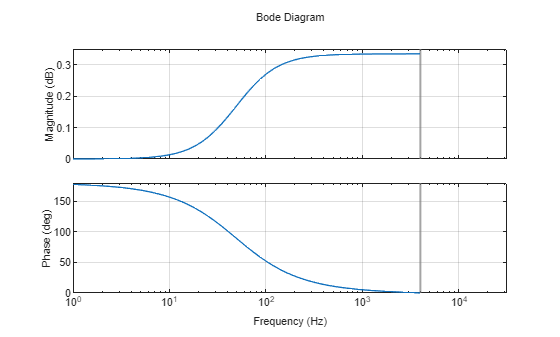

w_grid = 2*pi*f_grid;
apf = (s/w_grid-1)/(s/w_grid+1);
[napfd, dapfd]=tfdata(c2d(apf,ts_afe),'v');
apf_z = tf(napfd,dapfd,ts_afe,'Variable','z');
[A,B,C,D] = tf2ss(napfd,dapfd);
ap_flt_ss = ss(A,B,C,D,ts_afe);
figure;
bode(ap_flt_ss,options);
grid on

## INVERTER Settings and Initialization

### Mode of operation

motor_use_speed_control_mode = 0; 
motor_torque_mode = 1 - motor_use_speed_control_mode; % system uses torque curve for wind application
use_psm_encoder = 0;
use_load_estimator = 0;
use_estimator_from_mb = 0;

### Switching frequencies, sampling time and deadtime

% fPWM_INV = fPWM_AFE;
fPWM_INV = 2500;
dead_time_INV = 0;
delayINV_modA = 0;
pwm_out_lim = 1;

ts_inv = 1/fPWM_INV/2;
t_measure = simlength;
Ns_inv = floor(t_measure/ts_inv);
s=tf('s');
z=tf('z',ts_inv);


### INVERTER nominal current

if (application690 == 1)
    Iinv_phase_normalization_factor = 370*sqrt(2);
elseif (application480 == 1)
    Iinv_phase_normalization_factor = 470*sqrt(2);
else
    Iinv_phase_normalization_factor = 470*sqrt(2);
end

### MOTOR Selection from Library

if (application690 == 1)
    run('virtual_psm_18rpm_250kW_690V');
    run('virtual_torque_curve_psm_18rpm_250kW_690V');
    b = tau_bez/omega_m_bez;
else
    run('virtual_psm_18rpm_250kW_400V');
    run('virtual_torque_curve_psm_18rpm_250kW_400V');
    b = tau_bez/omega_m_bez;
end

tau_bez =      1.439118047344250e+05

vg_dclink =      9.661825271089831e+02

### Simulation parameters: inverter output di/dt filter

if (application690 == 1)
    LFi = 230e-6;
    RLFi = 5e-3;
else
    LFi = 180e-6;
    RLFi = 5e-3;
end

### Simulation parameters: speed reference, load torque in motor mode

rpm_sim = rpm_bez;
omega_m_sim = omega_m_bez;
omega_sim = omega_m_sim*number_poles/2;
tau_load_sim = tau_bez/5; %N*m
b_square = 0;
use_mtpa = 1;


### Luenberger Observer

Aso = [1 ts_inv; 0 1];
Cso = [1 0];
% p2place = exp([-10 -50]*ts_inv);
p2place = exp([-50 -250]*ts_inv);
Kobs = (acker(Aso',Cso',p2place))';
kg = Kobs(1)

kg =    0.058720741750118

kw = Kobs(2)

kw =    2.426376671832986

### Rotor speed observer with load estimator

A = [0 1 0; 0 0 -1/Jm_norm; 0 0 0];
Alo = eye(3) + A*ts_inv;
Blo = [0; ts_inv/Jm_norm; 0];
Clo = [1 0 0];
p3place = exp([-1 -5 -25]*125*ts_inv);
Klo = (acker(Alo',Clo',p3place))';
luenberger_l1 = Klo(1)

luenberger_l1 =    0.606931756868082

luenberger_l2 = Klo(2)

luenberger_l2 =      3.449190983162575e+02

luenberger_l3 = Klo(3)

luenberger_l3 =   -0.220747293476412

omega_flt_fcut = 10;
% phase_compensation_omega = -pi/2-pi/12; % for motor mode
phase_compensation_omega = 0; % for generator mode


### Control settings

id_lim = 0.35;

#### rotor speed control

kp_w = 0.25;
ki_w = 8;
iq_lim = 1.6;

#### current control

kp_i = 0.5;
ki_i = 18;
kp_id = kp_i;
ki_id = ki_i;
kp_iq = kp_i;
ki_iq = ki_i;
CTRPIFF_CLIP_RELEASE = 0.001;

#### Field Weakening Control 

kp_fw = 0.05;
ki_fw = 1.8;


#### BEMF observer

emf_fb_p = 0.2;
emf_p = emf_fb_p*4/10;

emf_fb_p_ccaller_1 = emf_fb_p;
emf_p_ccaller_1 = emf_fb_p_ccaller_1*4/10;

emf_fb_p_ccaller_2 = emf_fb_p;
emf_p_ccaller_2 = emf_fb_p_ccaller_2*4/10;

#### Speed obserfer filter LPF 10Hz

fcut_10Hz_flt = 10;
omega_flt_g0 = fcut_10Hz_flt * ts_inv * 2*pi;
omega_flt_g1 = 1 - omega_flt_g0;

#### Motor Voltage to Udc Scaling

motorc_m_scale = 2/3*Vdc_bez/ubez;

### Lithium Ion Battery

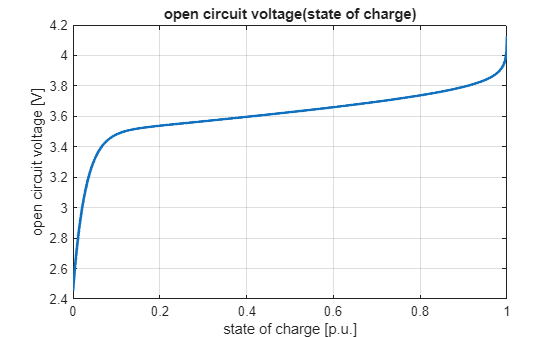

number_of_cells = floor(ubattery/3.6)-1; % nominal is 100

% stato of charge init
soc_init = 0.85; 

R = 8.3143;
F = 96487;
T = 273.15+40;
Q = 1000; %Hr*A

Vbattery_nom = ubattery;
Pbattery_nom = Pnom;
Ibattery_nom = Pbattery_nom/Vbattery_nom;
Rmax = Vbattery_nom^2/(Pbattery_nom*0.1);
Rmin = Vbattery_nom^2/(Pbattery_nom);

E_1 = -1.031;
% E0 = 3.685;
E0 = 3.485;
% E1 = 0.15;
E1 = 0.2156;
E2 = 0;
E3 = 0;
Elog = -0.05;
alpha = 35;

R0 = 0.0035;
R1 = 0.0035;
% R0 = 0.15;
% R1 = 0.15;
C1 = 0.5;
M = 125;


q1Kalman = ts_inv^2;
q2Kalman = ts_inv^1;
q3Kalman = 0;
rKalman = 1;

Zmodel = (0:1e-3:1);
ocv_model = E_1*exp(-Zmodel*alpha) + E0 + E1*Zmodel + E2*Zmodel.^2 +...
    E3*Zmodel.^3 + Elog*log(1-Zmodel+ts_inv);
figure; 
plot(Zmodel,ocv_model,'LineWidth',2);
xlabel('state of charge [p.u.]');
ylabel('open circuit voltage [V]');
title('open circuit voltage(state of charge)');
grid on

## C-Caller Settings

model = 'three_phase_dab';
open_system(model);
% Simulink.importExternalCTypes(model,'Names',{'mavgflt_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'bemf_obsv_load_est_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqvector_pi_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'sv_pwm_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'global_state_machine_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'first_harmonic_tracker_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqpll_thyr_output_t'});
% Simulink.importExternalCTypes(model,'Names',{'dqpll_grid_output_t'});

## Remove Scopes Opening Automatically

% shh = get(0,'ShowHiddenHandles');
% set(0,'ShowHiddenHandles','On');
% hscope = findobj(0,'Type','Figure','Tag','SIMULINK_SIMSCOPE_FIGURE');
% close(hscope);
% set(0,'ShowHiddenHandles',shh);
